h = [1,-1,1];
Fs = 1e6;
fg = 1e3;

H = fft(h);

v = 0:3;
N = Fs / fg;
H = [H zeros(1, N - length(h))];
x = 0:500;

subplot(2,1,1);
grid on;
plot(x, 20*log10(abs(H(1, 1:501))));
xlabel("Frequenz f in kHz");
ylabel("Amplitude in dB");

subplot(2,1,2);
grid on;
plot(x, 20*log(rad2deg(imag(H(1, 1:501)))));

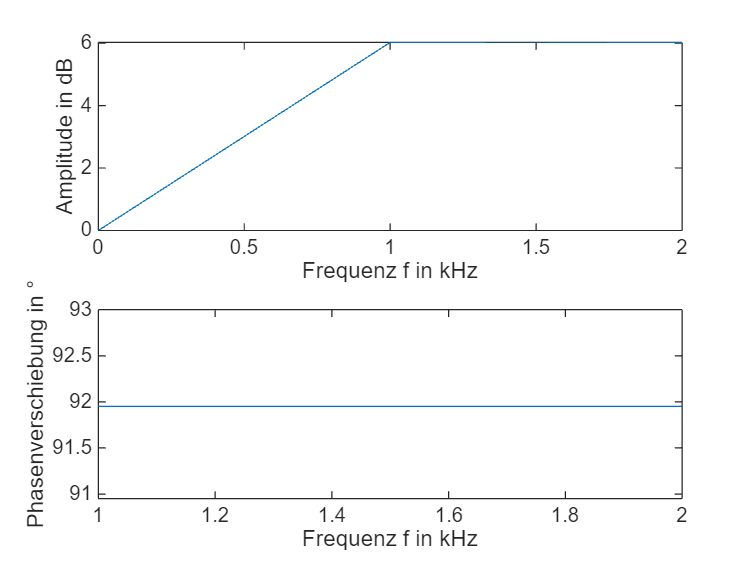

xlabel("Frequenz f in kHz");
ylabel("Phasenverschiebung in °");